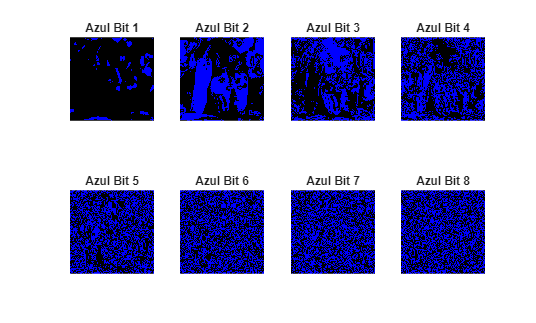

clc; clear; close all;
tic

%% ===== LECTURA Y SEPARACIÓN RGB =====
img = imread('C:\Users\marlo\OneDrive\Documentos\Mis documentos\UD\COMPLEX\pepers.jpg');
rojo  = img(:,:,1);
verde = img(:,:,2);
azul  = img(:,:,3);
[filas, columnas, ~] = size(img);

lienzo_negro = zeros(filas, columnas, 3, 'uint8');
img_roja  = lienzo_negro; img_roja(:,:,1)  = rojo;
img_verde = lienzo_negro; img_verde(:,:,2) = verde;
img_azul  = lienzo_negro; img_azul(:,:,3)  = azul;

figure;
subplot(2,2,1); imshow(img);       title('Original')
subplot(2,2,2); imshow(img_roja);  title('Capa Roja')
subplot(2,2,3); imshow(img_verde); title('Capa Verde')
subplot(2,2,4); imshow(img_azul);  title('Capa Azul')

%% ===== PARÁMETROS GLOBALES =====
x0_key  = -0.1;  y0_key  = 0.5;  z0_key  = -0.6;
N0_chen = 1000;
N_pixel = filas * columnas;

x0_ca = x0_key + 0.333;
y0_ca = y0_key - 0.111;
z0_ca = z0_key + 0.777;
N0_ca = 500;

%% ===== PLANOS DE BITS ORIGINALES =====
rojo_bin  = zeros(filas, columnas, 8, 'logical');
verde_bin = zeros(filas, columnas, 8, 'logical');
azul_bin  = zeros(filas, columnas, 8, 'logical');
for k = 1:8
    rojo_bin(:,:,k)  = bitget(rojo,  9-k);
    verde_bin(:,:,k) = bitget(verde, 9-k);
    azul_bin(:,:,k)  = bitget(azul,  9-k);
end

mapa_rojo  = [0 0 0; 1 0 0];
mapa_verde = [0 0 0; 0 1 0];
mapa_azul  = [0 0 0; 0 0 1];

figure('Name','Planos Originales (ROJO)');
for k=1:8, subplot(2,4,k); imshow(rojo_bin(:,:,k)); colormap(gca,mapa_rojo); title(['Rojo Bit ',num2str(k)]); end
figure('Name','Planos Originales (VERDE)');
for k=1:8, subplot(2,4,k); imshow(verde_bin(:,:,k)); colormap(gca,mapa_verde); title(['Verde Bit ',num2str(k)]); end
figure('Name','Planos Originales (AZUL)');
for k=1:8, subplot(2,4,k); imshow(azul_bin(:,:,k)); colormap(gca,mapa_azul); title(['Azul Bit ',num2str(k)]); end


%% ===== INTRA-BIT =====
rojo_perm  = zeros(size(rojo_bin),  'logical');
verde_perm = zeros(size(verde_bin), 'logical');
azul_perm  = zeros(size(azul_bin),  'logical');
circuits   = cell(1,8);

for k = 1:8
    z0_k = z0_key + (k-1) * 1e-4;
    [Sx_k, Sy_k, Sz_k] = chenSequence(x0_key, y0_key, z0_k, N0_chen, N_pixel);
    [bp_perm_R, Gmask, ~] = intraBitPermutation(rojo_bin(:,:,k), Sx_k);
    rojo_perm(:,:,k) = bp_perm_R;
    circuits{k} = buildIntraBitCircuit(Gmask);
    [bp_perm_G, ~, ~] = intraBitPermutation(verde_bin(:,:,k), Sy_k);
    verde_perm(:,:,k) = bp_perm_G;
    [bp_perm_B, ~, ~] = intraBitPermutation(azul_bin(:,:,k), Sz_k);
    azul_perm(:,:,k) = bp_perm_B;
end

figure('Name','Planos Intra-Bit (ROJO)');
for k=1:8, subplot(2,4,k); imshow(rojo_perm(:,:,k)); colormap(gca,mapa_rojo); title(['Rojo intra ',num2str(k)]); end
figure('Name','Planos Intra-Bit (VERDE)');
for k=1:8, subplot(2,4,k); imshow(verde_perm(:,:,k)); colormap(gca,mapa_verde); title(['Verde intra ',num2str(k)]); end
figure('Name','Planos Intra-Bit (AZUL)');
for k=1:8, subplot(2,4,k); imshow(azul_perm(:,:,k)); colormap(gca,mapa_azul); title(['Azul intra ',num2str(k)]); end

%% ===== RECONSTRUCCIÓN TRAS INTRA-BIT =====
R_reconstruido = zeros(filas, columnas, 'uint8');
G_reconstruido = zeros(filas, columnas, 'uint8');
B_reconstruido = zeros(filas, columnas, 'uint8');
for k = 1:8
    pos = 9 - k;
    R_reconstruido = bitset(R_reconstruido, pos, rojo_perm(:,:,k));
    G_reconstruido = bitset(G_reconstruido, pos, verde_perm(:,:,k));
    B_reconstruido = bitset(B_reconstruido, pos, azul_perm(:,:,k));
end

%% ===== ETAPA CA: AUTÓMATAS CELULARES =====
R_ca = cellularAutomatonEncryption(R_reconstruido, x0_ca, y0_ca, z0_ca,       N0_ca, true, false);
G_ca = cellularAutomatonEncryption(G_reconstruido, x0_ca, y0_ca, z0_ca + 0.1, N0_ca, true, false);
B_ca = cellularAutomatonEncryption(B_reconstruido, x0_ca, y0_ca, z0_ca + 0.2, N0_ca, true, false);

lienzo_negro = zeros(filas, columnas, 3, 'uint8');
R_ca_vis = lienzo_negro; R_ca_vis(:,:,1) = R_ca;
G_ca_vis = lienzo_negro; G_ca_vis(:,:,2) = G_ca;
B_ca_vis = lienzo_negro; B_ca_vis(:,:,3) = B_ca;
img_ca_rgb = cat(3, R_ca, G_ca, B_ca);

figure('Name','Canales tras Autómatas Celulares (CA)', 'Position', [100 100 1100 700]);
subplot(2,3,1); imshow(R_ca_vis);  title('Rojo — post CA',  'FontSize',11);
subplot(2,3,2); imshow(G_ca_vis);  title('Verde — post CA', 'FontSize',11);
subplot(2,3,3); imshow(B_ca_vis);  title('Azul — post CA',  'FontSize',11);
subplot(2,3,4); imshow(img);        title('Original (ref)',  'FontSize',11);
subplot(2,3,5); imshow(img_ca_rgb); title('RGB — post CA',   'FontSize',11);

R_ca_planes = zeros(filas, columnas, 8, 'logical');
G_ca_planes = zeros(filas, columnas, 8, 'logical');
B_ca_planes = zeros(filas, columnas, 8, 'logical');
for k = 1:8
    R_ca_planes(:,:,k) = bitget(R_ca, 9-k);
    G_ca_planes(:,:,k) = bitget(G_ca, 9-k);
    B_ca_planes(:,:,k) = bitget(B_ca, 9-k);
end

figure('Name','Planos post-CA (ROJO)');
for k=1:8, subplot(2,4,k); imshow(R_ca_planes(:,:,k)); colormap(gca,mapa_rojo); title(['R-CA Bit ',num2str(k)]); end
figure('Name','Planos post-CA (VERDE)');
for k=1:8, subplot(2,4,k); imshow(G_ca_planes(:,:,k)); colormap(gca,mapa_verde); title(['G-CA Bit ',num2str(k)]); end
figure('Name','Planos post-CA (AZUL)');
for k=1:8, subplot(2,4,k); imshow(B_ca_planes(:,:,k)); colormap(gca,mapa_azul); title(['B-CA Bit ',num2str(k)]); end

%% ===== DIFUSIÓN CAÓTICA =====
[Sx_diff, Sy_diff, Sz_diff] = chenSequence(x0_key, y0_key, z0_key + 0.1, N0_chen, N_pixel);
R_cifrado = chaoticDiffusion(R_ca, Sx_diff);
G_cifrado = chaoticDiffusion(G_ca, Sy_diff);
B_cifrado = chaoticDiffusion(B_ca, Sz_diff);
img_cifrada_final = cat(3, R_cifrado, G_cifrado, B_cifrado);

%% ===== VISUALIZACIÓN COMPARATIVA FINAL =====
R_cifr_vis = lienzo_negro; R_cifr_vis(:,:,1) = R_cifrado;
G_cifr_vis = lienzo_negro; G_cifr_vis(:,:,2) = G_cifrado;
B_cifr_vis = lienzo_negro; B_cifr_vis(:,:,3) = B_cifrado;

figure('Name','Comparativa de Encriptación','Position',[100 100 1200 800]);
subplot(3,3,1); imshow(img_roja);          title('Rojo Original');
subplot(3,3,2); imshow(img_verde);         title('Verde Original');
subplot(3,3,3); imshow(img_azul);          title('Azul Original');
subplot(3,3,4); imshow(R_cifr_vis);        title('Rojo Cifrado');
subplot(3,3,5); imshow(G_cifr_vis);        title('Verde Cifrado');
subplot(3,3,6); imshow(B_cifr_vis);        title('Azul Cifrado');
subplot(3,3,7); imshow(img);               title('Imagen Original (RGB)');
subplot(3,3,8); imshow(img_cifrada_final); title('Imagen Cifrada Final (RGB)');

%% =====================================================================
%% DESENCRIPTACIÓN
%% =====================================================================

R_perm_rec = inverseChaoticDiffusion(img_cifrada_final(:,:,1), Sx_diff);
G_perm_rec = inverseChaoticDiffusion(img_cifrada_final(:,:,2), Sy_diff);
B_perm_rec = inverseChaoticDiffusion(img_cifrada_final(:,:,3), Sz_diff);

R_ca_dec = cellularAutomatonEncryption(R_perm_rec, x0_ca, y0_ca, z0_ca,       N0_ca, false, false);
G_ca_dec = cellularAutomatonEncryption(G_perm_rec, x0_ca, y0_ca, z0_ca + 0.1, N0_ca, false, false);
B_ca_dec = cellularAutomatonEncryption(B_perm_rec, x0_ca, y0_ca, z0_ca + 0.2, N0_ca, false, false);

bitplanes_R = zeros(filas, columnas, 8, 'logical');
bitplanes_G = zeros(filas, columnas, 8, 'logical');
bitplanes_B = zeros(filas, columnas, 8, 'logical');
for k = 1:8
    bitplanes_R(:,:,k) = logical(bitget(R_ca_dec, 9-k));
    bitplanes_G(:,:,k) = logical(bitget(G_ca_dec, 9-k));
    bitplanes_B(:,:,k) = logical(bitget(B_ca_dec, 9-k));
end

for k = 1:8
    z0_k = z0_key + (k-1) * 1e-4;
    [Sx_k, Sy_k, Sz_k] = chenSequence(x0_key, y0_key, z0_k, N0_chen, N_pixel);
    perm_R = getPermutationFromChaos(Sx_k);
    perm_G = getPermutationFromChaos(Sy_k);
    perm_B = getPermutationFromChaos(Sz_k);
    bitplanes_R(:,:,k) = inverseIntraBitPermutation(bitplanes_R(:,:,k), perm_R);
    bitplanes_G(:,:,k) = inverseIntraBitPermutation(bitplanes_G(:,:,k), perm_G);
    bitplanes_B(:,:,k) = inverseIntraBitPermutation(bitplanes_B(:,:,k), perm_B);
end

img_original_R = zeros(filas, columnas, 'uint8');
img_original_G = zeros(filas, columnas, 'uint8');
img_original_B = zeros(filas, columnas, 'uint8');
for k = 1:8
    pos = 9 - k;
    img_original_R = bitset(img_original_R, pos, bitplanes_R(:,:,k));
    img_original_G = bitset(img_original_G, pos, bitplanes_G(:,:,k));
    img_original_B = bitset(img_original_B, pos, bitplanes_B(:,:,k));
end
img_desencriptada = cat(3, img_original_R, img_original_G, img_original_B);

figure('Name','Proceso Finalizado');
subplot(1,2,1); imshow(img_cifrada_final); title('Imagen Cifrada');
subplot(1,2,2); imshow(img_desencriptada); title('Imagen Recuperada');

tiempofinal = toc;
fprintf('Tiempo total: %.4f segundos\n', tiempofinal);

Tiempo total: 16.0320 segundos


diferencia = sum(abs(double(img(:)) - double(img_desencriptada(:))));
if diferencia == 0
    fprintf('Validación: Imágenes 100%% idénticas. Diferencia = 0.\n');
else
    fprintf('Error: Pérdida de información. Diferencia = %d\n', diferencia);
end

Validación: Imágenes 100% idénticas. Diferencia = 0.


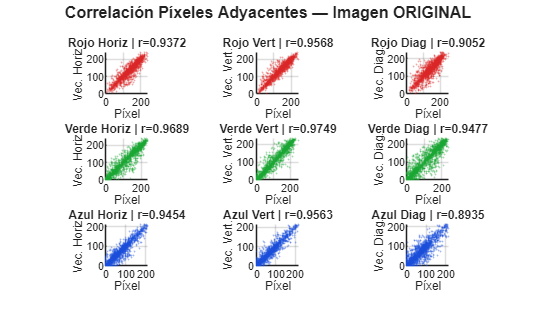


%% =====================================================================
%% ANÁLISIS DE SEGURIDAD — HISTOGRAMAS Y CORRELACIÓN
%% =====================================================================

%% --- 1. HISTOGRAMAS por canal (Original vs Cifrada) ---
figure('Name','Histogramas RGB — Original vs Cifrada','Position',[50 50 1300 750]);
canales_orig = {double(rojo), double(verde), double(azul)};
canales_cifd = {double(img_cifrada_final(:,:,1)), ...
                double(img_cifrada_final(:,:,2)), ...
                double(img_cifrada_final(:,:,3))};
nombres  = {'Rojo','Verde','Azul'};
colores  = {[0.85 0.15 0.15],[0.10 0.65 0.20],[0.10 0.30 0.85]};

for ch = 1:3
    subplot(2,3,ch);
    histogram(canales_orig{ch}(:), 0:256, 'FaceColor', colores{ch}, ...
              'EdgeColor','none','FaceAlpha',0.85);
    title([nombres{ch},' — Original'],'FontSize',10);
    xlabel('Nivel de gris'); ylabel('Frecuencia');
    xlim([0 255]); grid on;

    subplot(2,3,ch+3);
    histogram(canales_cifd{ch}(:), 0:256, 'FaceColor', colores{ch}, ...
              'EdgeColor','none','FaceAlpha',0.85);
    title([nombres{ch},' — Cifrada'],'FontSize',10);
    xlabel('Nivel de gris'); ylabel('Frecuencia');
    xlim([0 255]); grid on;
end
sgtitle('Histogramas: Original (fila 1) vs Cifrada (fila 2)','FontSize',12,'FontWeight','bold');

%% --- 2. CORRELACIÓN DE PÍXELES ADYACENTES ---
% Se muestran scatterplots horizontal, vertical y diagonal
% para cada canal antes y después del cifrado.
% Se calcula el coeficiente de correlación de Pearson r.

nMuestra = 3000;   % pares a grafidar para no saturar la figura
rng(42);           % semilla reproducible para el muestreo

figure('Name','Correlación Píxeles Adyacentes — Original','Position',[50 50 1300 750]);
figCount = 1;
for ch = 1:3
    orig_ch = canales_orig{ch};
    [rH, cH, rV, cV, rD, cD] = extraerPares(orig_ch, nMuestra);

    subplot(3,3,figCount);
    scatter(rH, cH, 2, colores{ch}, 'filled', 'MarkerFaceAlpha', 0.4);
    rxy = corrcoef(rH, cH); r_val = rxy(1,2);
    title(sprintf('%s Horiz | r=%.4f', nombres{ch}, r_val),'FontSize',9);
    xlabel('Píxel'); ylabel('Vec. Horiz.'); axis square; grid on;

    subplot(3,3,figCount+1);
    scatter(rV, cV, 2, colores{ch}, 'filled', 'MarkerFaceAlpha', 0.4);
    rxy = corrcoef(rV, cV); r_val = rxy(1,2);
    title(sprintf('%s Vert | r=%.4f', nombres{ch}, r_val),'FontSize',9);
    xlabel('Píxel'); ylabel('Vec. Vert.'); axis square; grid on;

    subplot(3,3,figCount+2);
    scatter(rD, cD, 2, colores{ch}, 'filled', 'MarkerFaceAlpha', 0.4);
    rxy = corrcoef(rD, cD); r_val = rxy(1,2);
    title(sprintf('%s Diag | r=%.4f', nombres{ch}, r_val),'FontSize',9);
    xlabel('Píxel'); ylabel('Vec. Diag.'); axis square; grid on;

    figCount = figCount + 3;
end
sgtitle('Correlación Píxeles Adyacentes — Imagen ORIGINAL','FontSize',12,'FontWeight','bold');

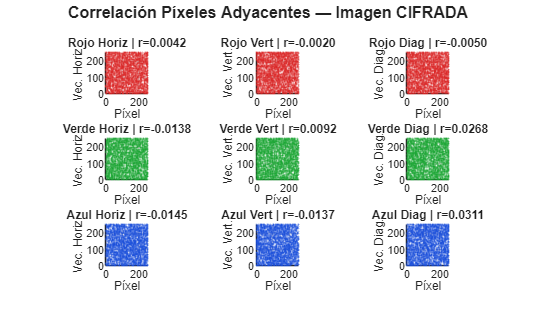


figure('Name','Correlación Píxeles Adyacentes — Cifrada','Position',[50 50 1300 750]);
figCount = 1;
for ch = 1:3
    cifd_ch = canales_cifd{ch};
    [rH, cH, rV, cV, rD, cD] = extraerPares(cifd_ch, nMuestra);

    subplot(3,3,figCount);
    scatter(rH, cH, 2, colores{ch}, 'filled', 'MarkerFaceAlpha', 0.4);
    rxy = corrcoef(rH, cH); r_val = rxy(1,2);
    title(sprintf('%s Horiz | r=%.4f', nombres{ch}, r_val),'FontSize',9);
    xlabel('Píxel'); ylabel('Vec. Horiz.'); axis square; grid on;

    subplot(3,3,figCount+1);
    scatter(rV, cV, 2, colores{ch}, 'filled', 'MarkerFaceAlpha', 0.4);
    rxy = corrcoef(rV, cV); r_val = rxy(1,2);
    title(sprintf('%s Vert | r=%.4f', nombres{ch}, r_val),'FontSize',9);
    xlabel('Píxel'); ylabel('Vec. Vert.'); axis square; grid on;

    subplot(3,3,figCount+2);
    scatter(rD, cD, 2, colores{ch}, 'filled', 'MarkerFaceAlpha', 0.4);
    rxy = corrcoef(rD, cD); r_val = rxy(1,2);
    title(sprintf('%s Diag | r=%.4f', nombres{ch}, r_val),'FontSize',9);
    xlabel('Píxel'); ylabel('Vec. Diag.'); axis square; grid on;

    figCount = figCount + 3;
end
sgtitle('Correlación Píxeles Adyacentes — Imagen CIFRADA','FontSize',12,'FontWeight','bold');


%% --- 3. TABLA RESUMEN DE CORRELACIONES EN CONSOLA ---
fprintf('\n========== TABLA DE CORRELACIONES ==========\n');


========== TABLA DE CORRELACIONES ==========


fprintf('%-8s %-10s %10s %10s %10s\n','Canal','Imagen','Horiz','Vert','Diag');

Canal    Imagen          Horiz       Vert       Diag


fprintf('%s\n', repmat('-',1,52));

----------------------------------------------------


for ch = 1:3
    for tipo = 1:2
        if tipo == 1
            canal_dat = canales_orig{ch};
            etq = 'Original';
        else
            canal_dat = canales_cifd{ch};
            etq = 'Cifrada ';
        end
        [rH,cH,rV,cV,rD,cD] = extraerPares(canal_dat, N_pixel);
        rH_c = corrcoef(rH,cH); rH_v = rH_c(1,2);
        rV_c = corrcoef(rV,cV); rV_v = rV_c(1,2);
        rD_c = corrcoef(rD,cD); rD_v = rD_c(1,2);
        fprintf('%-8s %-10s %10.6f %10.6f %10.6f\n', ...
            nombres{ch}, etq, rH_v, rV_v, rD_v);
    end
    fprintf('%s\n', repmat('-',1,52));
end

Rojo     Original     0.945820   0.958249   0.905240
Rojo     Cifrada      0.005363  -0.009635   0.001407


----------------------------------------------------


Verde    Original     0.969411   0.977875   0.946535
Verde    Cifrada      0.007106  -0.005387   0.001059


----------------------------------------------------


Azul     Original     0.941781   0.954378   0.898309
Azul     Cifrada     -0.002608  -0.019388  -0.004212


----------------------------------------------------



%% --- 4. ENTROPÍA DE LA INFORMACIÓN ---
fprintf('\n========== ENTROPÍA (bits) ==========\n');


========== ENTROPÍA (bits) ==========


fprintf('%-8s %12s %12s\n','Canal','Original','Cifrada');

Canal        Original      Cifrada


fprintf('%s\n', repmat('-',1,34));

----------------------------------


for ch = 1:3
    H_orig = entropiaShannon(canales_orig{ch}(:));
    H_cifd = entropiaShannon(canales_cifd{ch}(:));
    fprintf('%-8s %12.6f %12.6f\n', nombres{ch}, H_orig, H_cifd);
end

Rojo         7.376166     7.994652
Verde        7.684268     7.994996
Azul         7.171838     7.993776


fprintf('%s\n', repmat('-',1,34));

----------------------------------



%% --- 5. UACI y NPCR ---
% Comparación original vs cifrada (prueba de sensibilidad al plaintext)
fprintf('\n========== NPCR y UACI (Original vs Cifrada) ==========\n');


========== NPCR y UACI (Original vs Cifrada) ==========


fprintf('%-8s %10s %10s\n','Canal','NPCR (%%)','UACI (%%)');

Canal     NPCR (%%)  UACI (%%)


fprintf('%s\n', repmat('-',1,30));

------------------------------


for ch = 1:3
    [npcr_v, uaci_v] = calcularNPCR_UACI(canales_orig{ch}, canales_cifd{ch});
    fprintf('%-8s %10.4f %10.4f\n', nombres{ch}, npcr_v, uaci_v);
end

Rojo        99.5739    28.5563
Verde       99.6324    32.9456
Azul        99.5656    33.7479


fprintf('%s\n', repmat('-',1,30));

------------------------------


fprintf('  Referencia ideal: NPCR ≈ 99.6094%%  |  UACI ≈ 33.4635%%\n\n');

  Referencia ideal: NPCR ≈ 99.6094%  |  UACI ≈ 33.4635%





%% =====================================================================
%% FUNCIONES LOCALES — Pipeline base
%% =====================================================================

function [Sx, Sy, Sz] = chenSequence(x0, y0, z0, N0, N)
    a=35; b=3; c=28; dt=0.001;
    x=x0; y=y0; z=z0;
    function [xn,yn,zn] = rk4step(xi,yi,zi)
        f=@(xx,yy,zz)[a*(yy-xx);(c-a)*xx-xx*zz+c*yy;xx*yy-b*zz];
        k1=f(xi,yi,zi);
        k2=f(xi+dt/2*k1(1),yi+dt/2*k1(2),zi+dt/2*k1(3));
        k3=f(xi+dt/2*k2(1),yi+dt/2*k2(2),zi+dt/2*k2(3));
        k4=f(xi+dt*k3(1),yi+dt*k3(2),zi+dt*k3(3));
        dv=(k1+2*k2+2*k3+k4)/6;
        xn=xi+dt*dv(1); yn=yi+dt*dv(2); zn=zi+dt*dv(3);
    end
    for k=1:N0, [x,y,z]=rk4step(x,y,z); end
    rawX=zeros(1,N); rawY=zeros(1,N); rawZ=zeros(1,N);
    for k=1:N
        [x,y,z]=rk4step(x,y,z);
        rawX(k)=x; rawY(k)=y; rawZ(k)=z;
    end
    Sx=(rawX-min(rawX))/(max(rawX)-min(rawX)+eps);
    Sy=(rawY-min(rawY))/(max(rawY)-min(rawY)+eps);
    Sz=(rawZ-min(rawZ))/(max(rawZ)-min(rawZ)+eps);
end

function perm = getPermutationFromChaos(S)
    [~,perm]=sort(S,'ascend','ComparisonMethod','auto');
end

function [bp_perm, Gmask, perm] = intraBitPermutation(bp, S_channel)
    bp=logical(bp); [filas,columnas]=size(bp);
    perm=getPermutationFromChaos(S_channel);
    vector=bp(:); vector_perm=vector(perm);
    bp_perm=reshape(vector_perm,filas,columnas);
    Gmask=xor(bp,bp_perm);
end

function qc = buildIntraBitCircuit(Gmask)
    targetQubits=find(Gmask');
    if isempty(targetQubits)
        qc=quantumCircuit([],Name="IntraBit");
    else
        gates=xGate(targetQubits);
        qc=quantumCircuit(gates,Name="IntraBit");
    end
end

function img_diff = chaoticDiffusion(img, S_channel)
    [filas,columnas]=size(img); N=filas*columnas;
    K=uint8(floor(S_channel(:)*256)); P=img(:); V=bitxor(P,K);
    C=zeros(N,1,'uint8'); C(1)=V(1);
    for i=2:N, C(i)=bitxor(V(i),C(i-1)); end
    img_diff=reshape(C,filas,columnas);
end

function img = inverseChaoticDiffusion(img_diff, S_channel)
    [filas,columnas]=size(img_diff); N=filas*columnas;
    K=uint8(floor(S_channel(:)*256)); C=img_diff(:);
    P=zeros(N,1,'uint8'); P(1)=bitxor(C(1),K(1));
    temp_xor=bitxor(C(2:end),C(1:end-1));
    P(2:N)=bitxor(temp_xor,K(2:end));
    img=reshape(P,filas,columnas);
end

function bp = inverseIntraBitPermutation(bp_perm, perm)
    [filas,columnas]=size(bp_perm); vector=bp_perm(:);
    invperm(perm)=1:length(perm);
    bp=reshape(vector(invperm),filas,columnas);
end

%% =====================================================================
%% FUNCIONES DE ANÁLISIS DE SEGURIDAD
%% =====================================================================

% Extrae pares de píxeles adyacentes en las 3 direcciones.
% Devuelve nMuestra pares aleatorios de cada dirección.
function [rH,cH,rV,cV,rD,cD] = extraerPares(canal, nMuestra)
    [F,C] = size(canal);

    % Horizontal
    xi = canal(1:F, 1:C-1); yi = canal(1:F, 2:C);
    idx = randperm(numel(xi), min(nMuestra, numel(xi)));
    rH = double(xi(idx)); cH = double(yi(idx));

    % Vertical
    xi = canal(1:F-1, 1:C); yi = canal(2:F, 1:C);
    idx = randperm(numel(xi), min(nMuestra, numel(xi)));
    rV = double(xi(idx)); cV = double(yi(idx));

    % Diagonal
    xi = canal(1:F-1, 1:C-1); yi = canal(2:F, 2:C);
    idx = randperm(numel(xi), min(nMuestra, numel(xi)));
    rD = double(xi(idx)); cD = double(yi(idx));
end

% Entropía de Shannon en bits (base 2)
function H = entropiaShannon(v)
    counts = histcounts(v, 0:257);
    p = counts / sum(counts);
    p = p(p > 0);
    H = -sum(p .* log2(p));
end

% NPCR (Number of Pixels Change Rate) y UACI (Unified Average Changing Intensity)
function [npcr, uaci] = calcularNPCR_UACI(img1, img2)
    D = double(img1) ~= double(img2);
    npcr = 100 * sum(D(:)) / numel(D);
    uaci = 100 * sum(abs(double(img1(:)) - double(img2(:)))) / (255 * numel(img1));
end


%% =====================================================================
%% FUNCIÓN: Autómatas Celulares Compuestos (lógica Código 1)
%% =====================================================================

function channel_out = cellularAutomatonEncryption(channel, x0, y0, z0, N0, encrypt, verbose)
    if nargin < 7, verbose = false; end
    [rawX,rawY,rawZ] = chenRaw_ca(x0,y0,z0,N0,3);
    chaosVals = [rawX(1),rawY(1),rawZ(1)];
    [automatas,iteraciones] = deriveAutomataAndIterations_ca(chaosVals);
    if verbose
        fprintf('  [CA] x=%.10f  y=%.10f  z=%.10f\n',chaosVals(1),chaosVals(2),chaosVals(3));
        fprintf('  [CA] Automatas: %d %d %d  |  Iteraciones: %d %d %d\n', ...
            automatas(1),automatas(2),automatas(3), ...
            iteraciones(1),iteraciones(2),iteraciones(3));
    end
    recorr = {'col_up_lr','row_lr','col_up_rl'};
    rules  = getCompositeRuleTable_ca();
    [filas,columnas] = size(channel);
    channel_out = zeros(filas,columnas,'uint8');
    for k = 1:8
        bp = logical(bitget(channel,9-k));
        if encrypt, applyOrder=1:3; else, applyOrder=3:-1:1; end
        for idx = 1:3
            i   = applyOrder(idx);
            aid = automatas(i);
            t   = iteraciones(i);
            if encrypt, rule=rules(aid+1).enc; else, rule=rules(aid+1).dec; end
            bp = applyAutomatonByLines_ca(bp,rule,t,recorr{i});
        end
        channel_out = bitset(channel_out,9-k,bp);
    end
end

function [rawX,rawY,rawZ] = chenRaw_ca(x0,y0,z0,N0,N)
    a=35; b=3; c=28; dt=0.001;
    x=x0; y=y0; z=z0;
    for k=1:N0, [x,y,z]=rk4step_chen_ca(x,y,z,a,b,c,dt); end
    rawX=zeros(1,N); rawY=zeros(1,N); rawZ=zeros(1,N);
    for k=1:N
        [x,y,z]=rk4step_chen_ca(x,y,z,a,b,c,dt);
        rawX(k)=x; rawY(k)=y; rawZ(k)=z;
    end
end

function [xn,yn,zn] = rk4step_chen_ca(xi,yi,zi,a,b,c,dt)
    f=@(xx,yy,zz)[a*(yy-xx);(c-a)*xx-xx*zz+c*yy;xx*yy-b*zz];
    k1=f(xi,yi,zi);
    k2=f(xi+dt/2*k1(1),yi+dt/2*k1(2),zi+dt/2*k1(3));
    k3=f(xi+dt/2*k2(1),yi+dt/2*k2(2),zi+dt/2*k2(3));
    k4=f(xi+dt*k3(1),yi+dt*k3(2),zi+dt*k3(3));
    dv=(k1+2*k2+2*k3+k4)/6;
    xn=xi+dt*dv(1); yn=yi+dt*dv(2); zn=zi+dt*dv(3);
end

function [automatas,iteraciones] = deriveAutomataAndIterations_ca(vals)
    n=numel(vals); automatas=zeros(1,n); iteraciones=zeros(1,n);
    for i=1:n
        v=abs(vals(i)); frac=v-floor(v);
        automatas(i)=mod(floor(frac*1000),16);
        d1=floor(frac*10);
        d2=floor(frac*100)-d1*10;
        d3=floor(frac*1000)-floor(frac*100)*10;
        if     d3~=0, iteraciones(i)=d3;
        elseif d2~=0, iteraciones(i)=d2;
        elseif d1~=0, iteraciones(i)=d1;
        else,         iteraciones(i)=1;
        end
    end
end

function M = applyAutomatonByLines_ca(M,compRule,times,pathType)
    [R,C]=size(M);
    for t=1:times
        switch pathType
            case 'col_up_lr'
                buf=zeros(1,R*C); pos=1;
                for j=1:C, buf(pos:pos+R-1)=M(R:-1:1,j); pos=pos+R; end
                buf=processBuffer_ca(buf,compRule); pos=1;
                for j=1:C, M(R:-1:1,j)=buf(pos:pos+R-1); pos=pos+R; end
            case 'row_lr'
                buf=zeros(1,R*C); pos=1;
                for i=1:R, buf(pos:pos+C-1)=M(i,:); pos=pos+C; end
                buf=processBuffer_ca(buf,compRule); pos=1;
                for i=1:R, M(i,:)=buf(pos:pos+C-1); pos=pos+C; end
            case 'col_up_rl'
                buf=zeros(1,R*C); pos=1;
                for j=C:-1:1, buf(pos:pos+R-1)=M(R:-1:1,j); pos=pos+R; end
                buf=processBuffer_ca(buf,compRule); pos=1;
                for j=C:-1:1, M(R:-1:1,j)=buf(pos:pos+R-1); pos=pos+R; end
        end
    end
end

function buf = processBuffer_ca(buf,compRule)
    L=numel(buf); numBlocks=floor(L/8); original=buf;
    for b=1:numBlocks
        i0=(b-1)*8+1;
        idxs=mod((i0-1):(i0+6),L)+1;
        buf(idxs)=evolveOnce_ca(original(idxs),compRule);
    end
end

function ns = evolveOnce_ca(state,rule)
    n=numel(state); ns=zeros(1,n);
    for i=1:n
        Lv=state(mod(i-2,n)+1); Sv=state(i); Rv=state(mod(i,n)+1);
        ns(i)=applySymbol_ca(Lv,Sv,Rv,rule(i));
    end
end

function out = applySymbol_ca(L,S,R,sym)
    switch sym
        case 'A', out=L;   case 'B', out=S;   case 'C', out=R;
        case 'a', out=1-L; case 'b', out=1-S; case 'c', out=1-R;
        otherwise, error('Simbolo invalido: %s',sym);
    end
end

function rules = getCompositeRuleTable_ca()
    rules(16)=struct('id',[],'enc','','dec','');
    rules( 1)=struct('id', 0,'enc','AAAaaAaa','dec','CCccCccC');
    rules( 2)=struct('id', 1,'enc','AaaAaaAA','dec','ccCccCCC');
    rules( 3)=struct('id', 2,'enc','aAaaAAAa','dec','CccCCCcc');
    rules( 4)=struct('id', 3,'enc','aaAAAaaA','dec','cCCCccCc');
    rules( 5)=struct('id', 4,'enc','CCcCCccc','dec','aAAaAAaa');
    rules( 6)=struct('id', 5,'enc','ccCCcCCc','dec','aaaAAaAA');
    rules( 7)=struct('id', 6,'enc','CcccCCcC','dec','AAaaaAAa');
    rules( 8)=struct('id', 7,'enc','cCCcccCC','dec','AaAAaaaA');
    rules( 9)=struct('id', 8,'enc','BBbBCaca','dec','BBbBcAca');
    rules(10)=struct('id', 9,'enc','bcABcABb','dec','bCaBCaBb');
    rules(11)=struct('id',10,'enc','CabbBCaB','dec','cAbbBcAB');
    rules(12)=struct('id',11,'enc','bBCabbCA','dec','bBcAbbCA');
    rules(13)=struct('id',12,'enc','bcACAbbB','dec','bCaCAbbB');
    rules(14)=struct('id',13,'enc','bBbcACAb','dec','bBbCaCAb');
    rules(15)=struct('id',14,'enc','CABcaBbb','dec','CABcaBbb');
    rules(16)=struct('id',15,'enc','BbcAbcAB','dec','BbCabCaB');
end